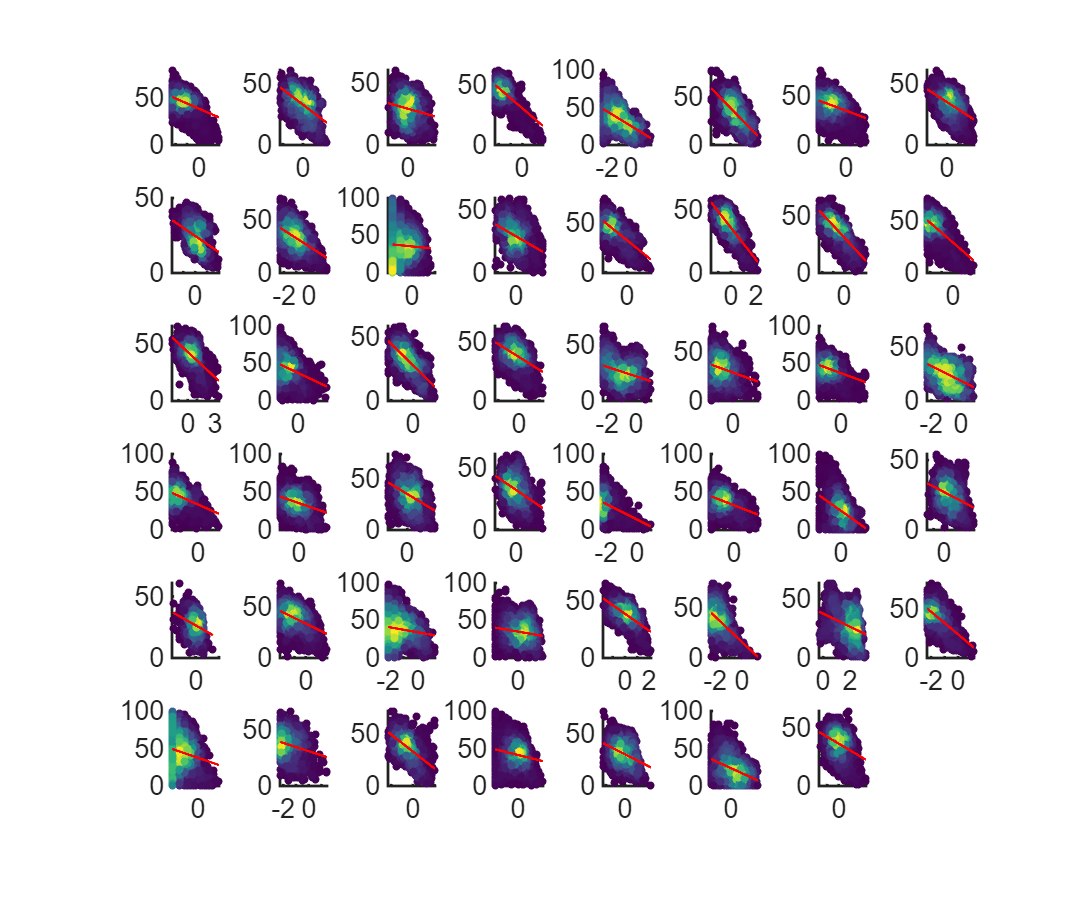

clc; clear; close all; addpath z_toolbox
load(fullfile('step4_IEDtw_polyfit_TD6d0', 'IEDtw_meth-None_TD-6d0.mat'));
figure('Units', 'centimeters', 'Position', [5, 5, 36, 30]);
for nS = 1:47
    IEDtwD = IEDtw(nS).indirectTransferDelayMatrix;
    IEDtwR = IEDtw(nS).indirectTransferRateMatrix;
    Mask = IEDtwR;
    Mask = Mask - diag(diag(Mask));
    Mask(isnan(Mask)) = 0;
    Mask(Mask<0.1) = 0;
    IEDtwD = IEDtwD(Mask>0);
    IEDtwR = IEDtwR(Mask>0);
    IEDtwR = log(IEDtwR);
    [polyModel, Curve, Ftest] = f_polyfit(IEDtwR, IEDtwD, 1);
    subplot(6, 8, nS);
    f_densityScatter(IEDtwR, IEDtwD, 2); hold on;
    plot(Curve.x, Curve.y, 'r-', 'LineWidth', 2); hold off;
    set(gca, 'box', 'off', 'FontName', 'Arial', 'FontSize', 20, 'LineWidth', 2);
end